# Implementando el método de la bisección

Autor(a): JUAN MANUEL MUSKUS MUSKUS - Universidad de Córdoba

## Resumen

*La actividad consiste en implementar y aplicar el ****método numérico de la bisección**** para aproximar la raíz de una función no lineal utilizando ****MATLAB Online****. Los estudiantes deberán programar un script que reciba como entrada una función continua definida en un intervalo [a,b] y, a partir del ****teorema de Bolzano****, itere hasta encontrar una aproximación de la raíz dentro de una tolerancia establecida.*

*Al finalizar, los estudiantes obtendrán una tabla con los valores intermedios, el error de aproximación en cada paso y la raíz estimada. Esta práctica permite reforzar habilidades en ****programación científica****, ****análisis de convergencia**** y ****uso de herramientas computacionales para la ingeniería****.*

***Palabras clave:**** método de bisección, MATLAB Online, raíces de funciones, métodos numéricos, enseñanza en línea, ingeniería.*

## Objetivos de Aprendizaje

Al finalizar esta actividad (2 horas de trabajo guiado en laboratorio de cómputo), los estudiantes de quinto semestre de Ingeniería de Sistemas serán capaces de **implementar en MATLAB el método de la bisección para aproximar la raíz de una función no lineal, documentar el proceso y analizar la convergencia del algoritmo**, evidenciando su capacidad para aplicar **conceptos de modelamiento matemático y métodos numéricos en la solución de problemas propios de la ingeniería**.

## Antes de empezar 

Este cuaderno computacional en MATLAB, o Live Script está diseñado para usarse con el código visible y mostrando los resultados en el cuaderno. En la pestaña **View** de las opciones de MATLAB (Toolstrip), en la sección **View**, seleccione **Output Inline**. De forma alternativa, seleccione **Output inline **usando el ícono  en la esquina derecha del editor del Live Script. 

 Interactuar con este Live Script le permitirá familiarizarse con MATLAB a medida que se introducen conceptos y comandos juntos. Si necesita más entrenamiento, considere realizar el curso [MATLAB Onramp](https://matlabacademy.mathworks.com/details/matlab-onramp/gettingstarted), un tutorial en línea de 2 horas que enseña los conceptos básicos de MATLAB. 

   Para una experiencia óptima, siga las instrucciones y pasos en la secuencia indicada. Pase a una nueva sección sólo después de completar la anterior. Algunas secciones dependen de variables creadas en secciones anteriores y generarán errores si se ejecutan en desorden.

En este cuaderno tendrá la oportunidad de explorar la visualización de conceptos introducidos, pero también podrá usar ejercicios que le permitirán interactuar con el código y desafiar su comprensión de esos conceptos y su profesor puede usarlas para calificar y verificar la finalización.

## Sección 1: Conceptos 

El **método de la bisección** es una técnica de búsqueda de raíces que se basa en el **Teorema de Bolzano**, el cual establece que si una función continua cambia de signo en un intervalo [a,b][a, b][a,b], entonces existe al menos una raíz dentro de ese intervalo.

Este método es uno de los algoritmos más robustos para la solución de ecuaciones no lineales, aunque su convergencia es más lenta en comparación con otros métodos (como Newton-Raphson o la secante).

**Conceptos clave que se abordarán en esta actividad:**

- Funciones continuas y condición de signo opuesto en los extremos del intervalo.

- Aplicación del Teorema de Bolzano.

- Iteraciones sucesivas dividiendo el intervalo a la mitad.

- Criterio de parada: tolerancia o número máximo de iteraciones.

- Análisis de convergencia y cálculo del error.

%% Ejemplo conceptual: función simple
f = @(x) x.^3 - x - 2;   % Definición de la función
a = 1; b = 2;            % Intervalo inicial

% Verificar condición de Bolzano
if f(a)*f(b) < 0
    disp('Se cumple la condición de Bolzano: existe al menos una raíz en [a,b].')
else
    disp('No se cumple la condición de Bolzano en este intervalo.')
end

Se cumple la condición de Bolzano: existe al menos una raíz en [a,b].


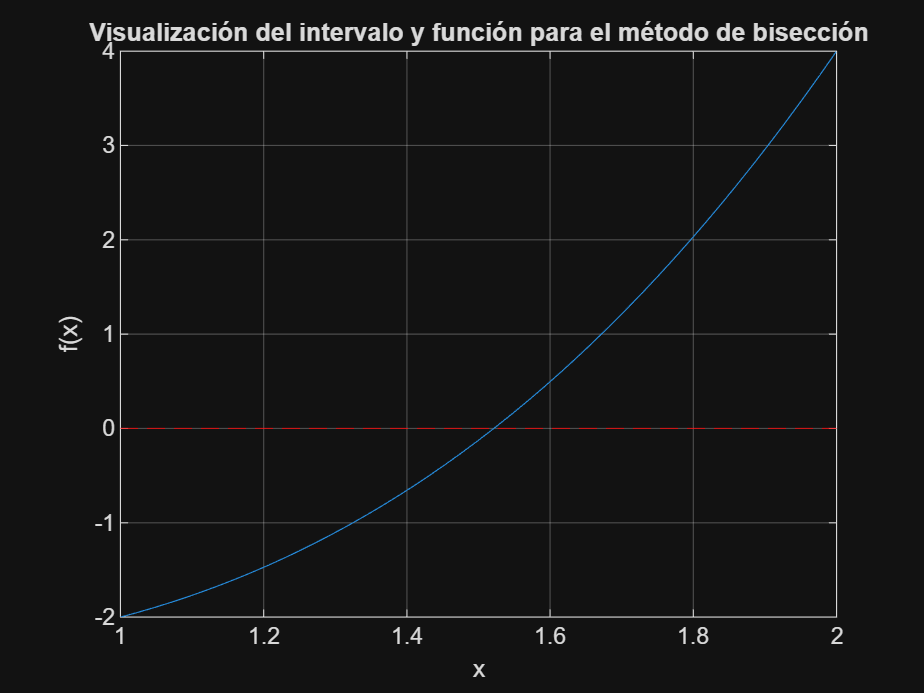


% Graficar la función en el intervalo
fplot(f,[a b])
hold on
yline(0,'--r')
xlabel('x')
ylabel('f(x)')
title('Visualización del intervalo y función para el método de bisección')
grid on

## Sección 2: Ejercicio 1

Implemente un script en MATLAB que, usando el método de la bisección, encuentre la raíz de la función:


$$f\left(x\right)=x^3 -x-2$$


en el intervalo $\left\lbrace 1,2\right\rbrace$ con una tolerancia de ${10}^{-5}$.

**Pasos sugeridos para los estudiantes:**

- Definir la función y el intervalo inicial.

- Implementar el algoritmo de la bisección.

- Guardar la raíz aproximada y el número de iteraciones.

- Mostrar los resultados en pantalla.

f = @(x) x.^3 - x - 2;   % Definición de la función
a = 1; b = 2;            % Intervalo inicial
tol = 1e-5;              % Tolerancia

% Implementa las iteraciones usando el ciclo while

## Sección 3: Ejercicio 2

Modifique el código anterior para resolver el siguiente problema:

Encuentre la raíz de la función:


$$f\left(x\right)=\cos \left(x\right)-x$$


en el intervalo $\left\lbrace 0,1\right\rbrace$ con una tolerancia de ${10}^{-6}$.

**Pasos sugeridos para los estudiantes:**

- Cambiar la definición de la función y el intervalo inicial.

- Ejecutar el algoritmo de la bisección.

- Analizar la convergencia y comparar la raíz obtenida con la solución aproximada en MATLAB usando `fzero`.

%% Ejercicio 2: Método de la bisección en otra función
f = @(x) cos(x) - x;     % Definición de la función
a = 0; b = 1;            % Intervalo inicial
tol = 1e-6;              % Tolerancia

% Implementa las iteraciones usando el ciclo while
% Escribe aqui tu codigo

% Comparar con fzero
raiz_fzero = fzero(f, [0 1]);
fprintf('Raíz con fzero: %.6f\n', raiz_fzero);

Raíz con fzero: 0.739085


## Recursos Adicionales

**Documentación y guías oficiales**

- **MATLAB Documentation – Root Finding**https://www.mathworks.com/help/matlab/ref/fzero.html

## Referencias 

- Burden, R. L., & Faires, J. D. (2017). *Análisis Numérico* (10ª ed.). Cengage Learning.

- Chapra, S. C. (2018). *Métodos Numéricos para Ingenieros* (7ª ed.). McGraw-Hill.

- Heath, M. T. (2018). *Scientific Computing: An Introductory Survey* (2ª ed.). McGraw-Hill.

- MathWorks. (2025). *MATLAB Documentation – Root Finding*. Recuperado de: https://www.mathworks.com/help/matlab/ref/fzero.html